% Oppgave b - Finn k for forsterkningsmargin på 12 dB ± 1 dB

% Definer overføringsfunksjonen G(s)
s = tf('s');
k = 1; % Start med en vilkårlig verdi
G = (10 * k * (1 + s/5)) / (s * (1 + s/0.4) * (1 + s/70) * (1 + s/120));

% Beregn Bode-plot og marginer for å justere k
target_margin = 12; % Ønsket forsterkningsmargin i dB
tolerance = 1;      % Toleranse for marginen

% Juster k iterativt
for k = 0.1:0.01:10 % Prøv verdier av k i området 0.1 til 10
    G_k = (10 * k * (1 + s/5)) / (s * (1 + s/0.4) * (1 + s/70) * (1 + s/120));
    [Gm, Pm, ~, ~] = margin(G_k); % Beregn marginer
    Gm_dB = 20 * log10(Gm); % Konverter forsterkningsmargin til dB
    
    % Sjekk om forsterkningsmarginen er innenfor målområdet
    if abs(Gm_dB - target_margin) <= tolerance
        fprintf('Funnet k: %.2f med forsterkningsmargin: %.2f dB\n', k, Gm_dB)
        break;
    end
end

% Plott Bode-plot for den funne k-verdien
G_final = (10 * k * (1 + s/5)) / (s * (1 + s/0.4) * (1 + s/70) * (1 + s/120))

G_final =
 
           336000 s + 1.68e06
  -------------------------------------
  5 s^4 + 952 s^3 + 42380 s^2 + 16800 s
 
Continuous-time transfer function.
Model Properties


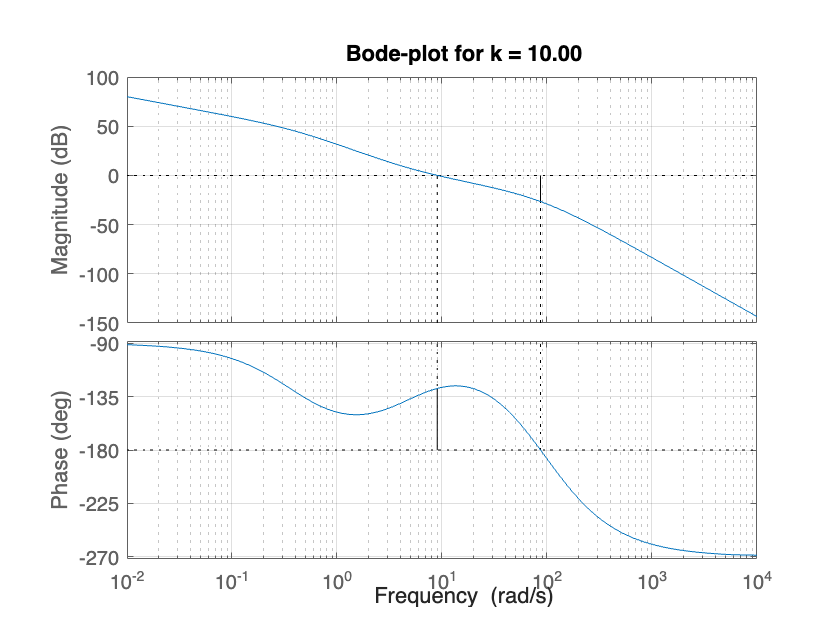

figure;
margin(G_final);
grid on;
title(sprintf('Bode-plot for k = %.2f', k));